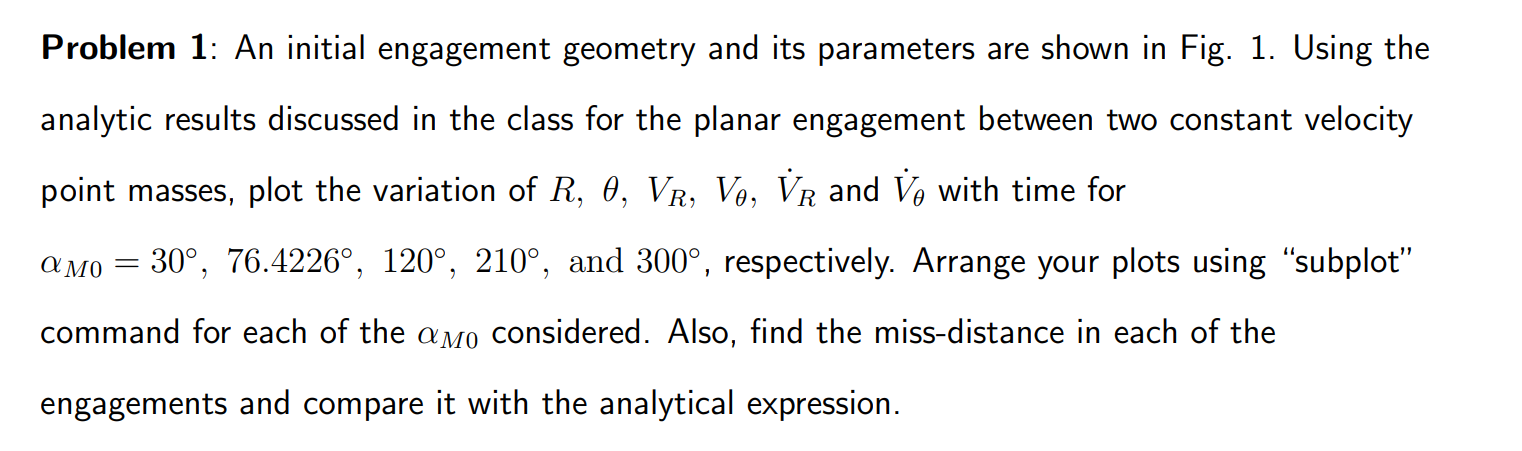

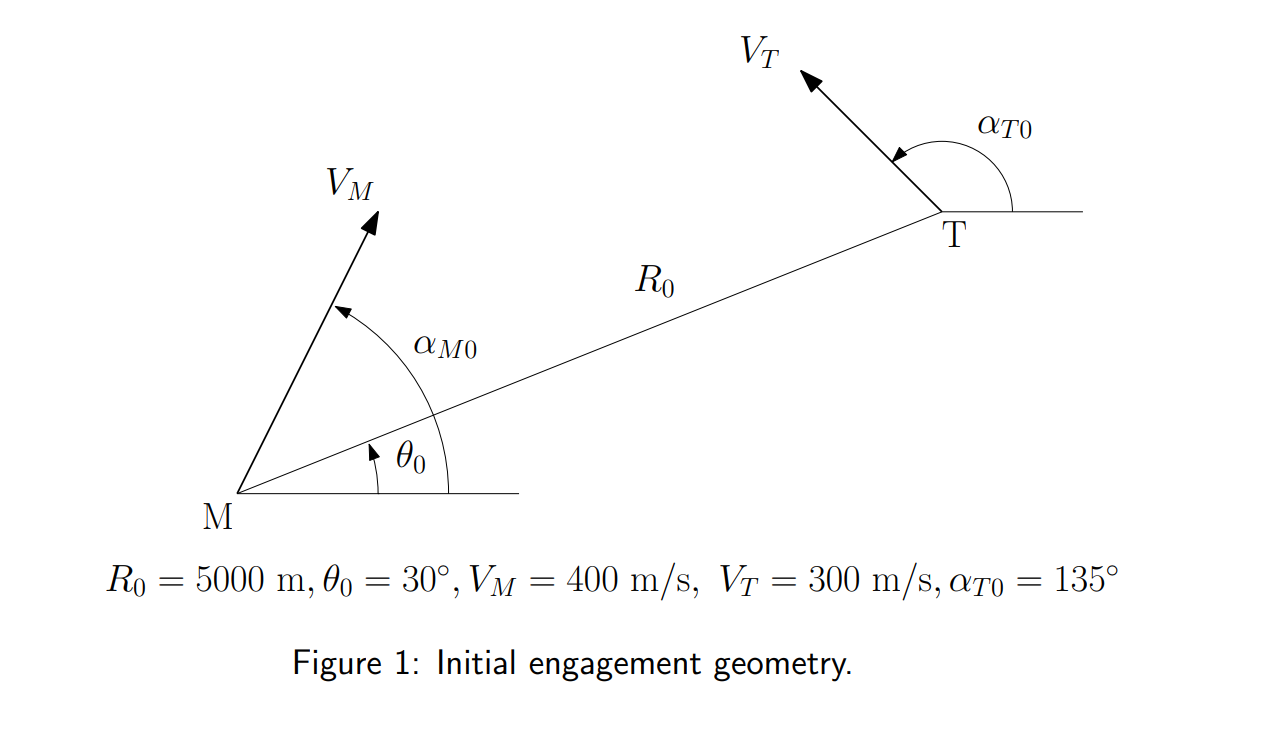

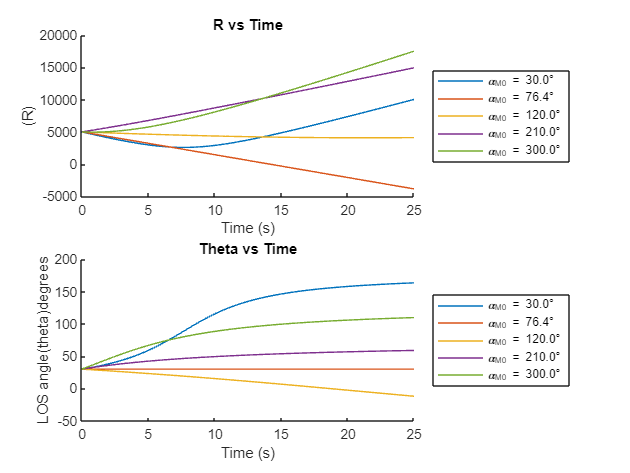

clc;
clear all;

%Intial condition
R0 = 5000; %meter
theta0 = deg2rad(30); 
V_M = 400; % m/s
V_T = 300; %m/s
alpha_T0 = deg2rad(135);
V_R0 = (V_T - V_M);
alpha_M0 = deg2rad([30, 76.4226, 120, 210, 300]);
alpha_M0_length = length(alpha_M0);

%timespan
dt=0.1;
tspan = 0:dt:25;

num_timesteps = length(tspan);

%store the values
R = zeros(num_timesteps,alpha_M0_length);
theta = zeros(num_timesteps,alpha_M0_length);
V_R = zeros(num_timesteps,alpha_M0_length);
V_theta = zeros(num_timesteps, alpha_M0_length);
V_R_dot = zeros(num_timesteps,alpha_M0_length);
V_theta_dot = zeros(num_timesteps,alpha_M0_length);

%Equations
for j =1:alpha_M0_length

    %options = odeset('Events', @projEvents);

    Eqn = @(t,y) missile_func(tspan,y,alpha_M0(j),V_M, V_T, alpha_T0);

    %ode45
    [t,Y] = ode45(Eqn, tspan, [R0, theta0]);

    R(:,j) = Y(:,1);
    theta(:,j) = Y(:,2);

    %V_R and V_theta
    for i = 1:num_timesteps
        V_R(i,j) = V_T * cos(alpha_T0 -theta(i,j)) - V_M * cos(alpha_M0(j) - theta(i,j));
        V_theta(i,j) = (1/R(i,j)) * (V_T * sin(alpha_T0 -theta(i,j)) - V_M * sin(alpha_M0(j) - theta(i,j)));
    end

    %V_R_dot and V_theta_dot
    V_R_dot(:,j) = gradient(V_R(:,j),t);
    V_theta_dot(:,j) = gradient(V_theta(:,j),t);

     %index when VR=0
    idx = find(V_R(:,j) >= 0, 1);
    if ~isempty(idx)
        
        t_miss = t(idx);
        R_miss(j) = interp1(t, R(:,j), t_miss);
    else
        R_miss(j) = NaN; % Nointerception 
    end

end

figure;
subplot(2,1,1)
hold on;
for j = 1:alpha_M0_length
    plot(tspan, R(:,j), 'DisplayName', sprintf('\\alpha_{M0} = %0.1f°', rad2deg(alpha_M0(j))));
    % hold on
    % pause(0.5);
end
title('R vs Time');
xlabel('Time (s)');
ylabel('(R)');
legend('Location', 'eastoutside');
%axis('equal')
hold off;

subplot(2,1,2)
hold on;
for j = 1:alpha_M0_length
    plot(tspan, theta(:,j) * (180/pi), 'DisplayName', sprintf('\\alpha_{M0} = %0.1f°', rad2deg(alpha_M0(j))));
end
title('Theta vs Time');
xlabel('Time (s)');
ylabel('LOS angle(theta)degrees');
legend('Location', 'eastoutside');
%axis('equal')
hold off;

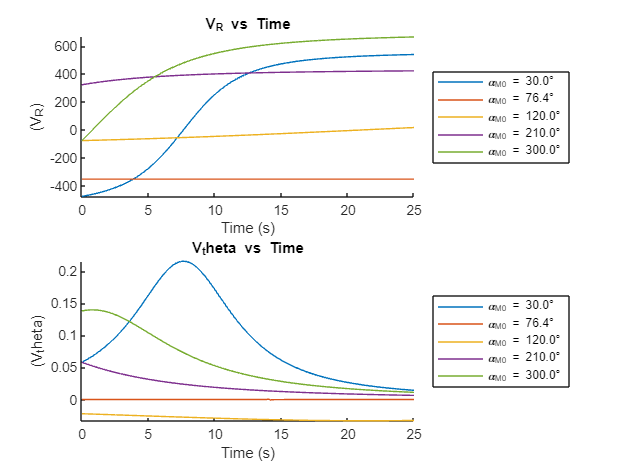


figure;
subplot(2,1,1)
hold on;
for j = 1:alpha_M0_length
    plot(tspan, V_R(:,j), 'DisplayName', sprintf('\\alpha_{M0} = %0.1f°', rad2deg(alpha_M0(j))));
end
title('V_R vs Time');
xlabel('Time (s)');
ylabel('(V_R)');
legend('Location', 'eastoutside');
%axis('equal')
hold off;

subplot(2,1,2)
hold on;
for j = 1:alpha_M0_length
    plot(tspan, V_theta(:,j), 'DisplayName', sprintf('\\alpha_{M0} = %0.1f°', rad2deg(alpha_M0(j))));
end
title('V_theta vs Time');
xlabel('Time (s)');
ylabel('(V_theta)');
legend('Location', 'eastoutside');
%axis('equal')
hold off;

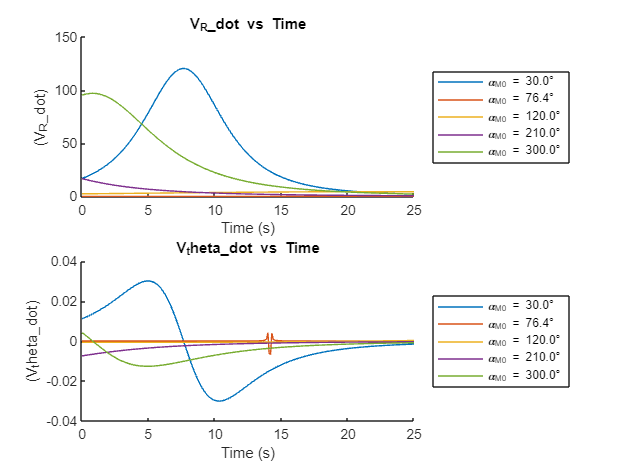

% %VR vs Vtheta
% figure;
% for j = 1:alpha_M0_length
%     plot( V_theta(:,j), V_R(:,j), 'DisplayName', sprintf('\\alpha_{M0} = %0.1f°', rad2deg(alpha_M0(j))));
%     hold on;
%     xlabel('theta');
%     ylabel('(V_R)');
%     legend('Location', 'eastoutside');
%     hold off;
% end




% Plot VR_dot vs. time
figure;
subplot(2,1,1)

hold on;
for j = 1:alpha_M0_length
    plot(tspan, V_R_dot(:,j), 'DisplayName', sprintf('\\alpha_{M0} = %0.1f°', rad2deg(alpha_M0(j))));
end
title('V_R\_dot vs Time');
xlabel('Time (s)');
ylabel('(V_R\_dot)');
legend('Location', 'eastoutside');
hold off;


% Plot Vtheta_dot vs. time
subplot(2,1,2)
hold on;
for j = 1:alpha_M0_length
    plot(tspan, V_theta_dot(:,j), 'DisplayName', sprintf('\\alpha_{M0} = %0.1f°', rad2deg(alpha_M0(j))));
end
title('V_theta\_dot vs Time');
xlabel('Time (s)');
ylabel('(V_theta\_dot)');
legend('Location', 'eastoutside');
hold off;

% Print R_miss values
fprintf('Simulation R_miss values:\n');

Simulation R_miss values:


for j = 1:alpha_M0_length
   fprintf('For alpha_M0 = %0.1f°, R_miss = %0.2f meters\n', rad2deg(alpha_M0(j)), R_miss(j)); 
end

For alpha_M0 = 30.0°, R_miss = 2593.58 meters
For alpha_M0 = 76.4°, R_miss = NaN meters
For alpha_M0 = 120.0°, R_miss = 4087.61 meters
For alpha_M0 = 210.0°, R_miss = 5000.00 meters
For alpha_M0 = 300.0°, R_miss = 4969.06 meters


function dydt = missile_func(~,y,alpha_M0,V_M,V_T,alpha_T0)
    R = y(1);
    theta = y(2);
    
    dRdt = (V_T * cos(alpha_T0 -theta) - V_M * cos(alpha_M0 - theta));
    dthetadt = (1/R) * (V_T * sin(alpha_T0 - theta) - V_M *sin(alpha_M0 - theta));

    dydt = [dRdt;dthetadt];
end
%%
% function [value,isterminal,direction] = projEvents(t,R)
%     value = R(1) - 0.1; % Detect R - 0.1 m
%     isterminal = 1; 
%     direction = -1;
% end